% reproduced graph from the main reference
% precipitation rate for Eastern and Western Pacific

listOfStations=["WDarwin.xlsx", "WJayapura.xlsx", "WMadang.xlsx", ...
    "WTarawa.xlsx", "WTruk.xlsx", "WYap.xlsx", "EApia.xlsx", ...
    "ECanton_Island.xlsx", "EChristmas_Island.xlsx"];

for i=1:9 %loop over all stations
        stations{i}=listOfStations(i); %get names of stations
        stationsRead{i}=readtable(stations{i}); %read data
        stationsConvert{i}=table2cell(stationsRead{i}); %convert data to cell array
end


columnNames=stationsRead{1}.Properties.VariableNames; %get column names of the data 
                                                      %(important for extracting information)
re_st=string(columnNames); %convert column names cell to readable string
date_index=find(strcmp(re_st,'Date')); %finds the index of the 'Date' - 
    % can be used for finding any name of the column


The data is not chronological: ordering data by date.

%Loop:

for i=1:length(stationsConvert)
    tempVar=stationsConvert{i}; %create new variable just for convenience
                        % - so to store the value stationsConvert{i} and
                        % avoid double indexing, which is the 
                        % problem in the last line (sorted{i}=...)
    allDatesofList_i=tempVar(:,date_index); % gives all dates in one cell
    dating_i = datetime(allDatesofList_i,'Format','yyyy-MM-dd'); % formats 
    % 'allDates' cell to an array datetime values

    [sortDates_i,originalIndex_i]=sort(dating_i); %sorts A array (708x1
    % - includes only dates) into ascending order. 
    % originalIndex gives the original index or s table

    sorted{i}=tempVar(originalIndex_i,:); %print s table with originalIndex, 
    % which gives data in ascending date
end

% simple visualisation of the data
% H3 variance wrt time

% SORT DATES ???? (HOW TO PLOT ALL OF THEM IN ONE GRAPH?)

According to the  reference *G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017 *on page 3707, the abundance of deuterium is measured with the following formula:


$$\delta D=\left(\frac{R_{\mathrm{sample}} }{R_{\mathrm{VSMOW}} }-1\right)\cdot 1000\text{ }‰$$


where:

$R_{\mathrm{sample}}$ is the ratio of deuterium to the common, stable isotope of hydrogen in the samples considered,

 $R_{\mathrm{VSMOW}}$ is the same ratio but for a reference sample with the isotopic composition of the Vienna standard mean ocean water.


$$R_{\text{VSMOW}} =155\ldotp 76\pm 0\ldotp 1ppm$$
 

$\delta D$ is already included in the IAEA WISER data. Therefore, we don't have to calculate it.

% Delta D versus precipitation rate per day

prec_index=find(strcmp(re_st,'Precipitation')); %finds the index for precipitation
H2_index=find(strcmp(re_st,'H2')); %finds the index for H2
graphdata={}; % this is where we will store our data - for now empty,
% but it will be a nested cell
for i=1:length(stationsConvert)
    % creates a cell, which stores precipitation in 1st., H2 in 2nd column
    deltaDprecip{i} = [sorted{i}(:,prec_index), sorted{i}(:,H2_index)];
    % delete NaN rows:
    %1. For rmmising to work, the cell needs to be converted to double array:
    ctm = rmmissing(cell2mat(deltaDprecip{i}));
    %2. Next, we need to convert it back to cell:
    nc_graphdata=mat2cell(ctm,[size(ctm,1)]); %next cell in graph data
    graphdata=[graphdata, nc_graphdata]; %append the cell to the overall 
    % 'graphdata' cell
end


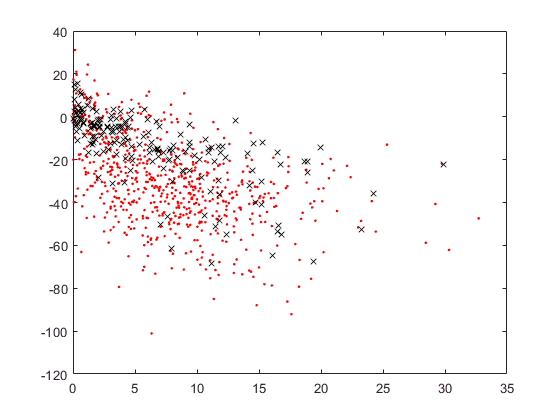

EoP_index=find(strcmp(re_st,'EndOfPeriod')); % the end of the month
BoP_index=find(strcmp(re_st,'BeginOfPeriod')); % the begining of the month

%Reading all dates
clf
%west k=1, east k=2
for k=[1,2]
    H2{k}={};
    pppday{k}={};
    if k==1
        it=[1:6];
    else
        it=[7:9];
    end
    for i=it % iterate over West
        for j=1:length(sorted{i}) % iterate  over each data point in each file 
    %       H3=sorted{i}(j,H3_index);   % -----------------
            new_H2{k}=sorted{i}(j,H2_index);   % get H3, H2 and O18 information for j row
%           O18=sorted{i}(j,O18_index); % -----------------
            EoP=sorted{i}(j,EoP_index); % get the date for begining to collect data
            BoP=sorted{i}(j,BoP_index); % get the date for end of collecting data
        %finding how many days the data was collected for row j 
        %(+1 because it doesn't count inclusively)
            numdays=(datenum(EoP)- datenum(BoP)+1);
        %precipitation per day
            new_pppday{k}=sorted{i}{j,prec_index}./numdays;
            pppday{k}=[pppday{k}, new_pppday{k}];
            H2{k}=[H2{k},new_H2{k}];
        end
    end
    
    if k==1
        ptCol='.red';
    else
        ptCol='xblack';
    end

    %see a scatter plot of the data
    pppdayTable{k}=cell2mat(pppday{k});
    H2Table{k}=cell2mat(H2{k});
    figure(1)
    plot(pppdayTable{k},H2Table{k},ptCol)
    hold on
end

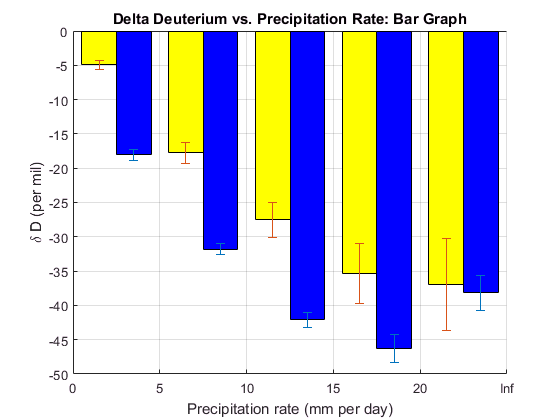

for k=[1,2]
    % Making bar graphs
    [pppdaybin{k},Edges]= discretize(pppdayTable{k},[0,5,10,15,20,Inf]);

    %I want to get the array of deltaH2 for each bin
    for m=1:(length(Edges)-1)
     %I use a structure as it is easier to use with loops
        H2binned{k}(m).H2{k}=H2{k}(pppdaybin{k} == m);
    end

    for m=1:(length(Edges)-1)
    %I then find the mean of these deltaH2 (along with the standard deviations
        H2binned{k}(m).mean = nanmean(cell2mat(H2binned{k}(m).H2{k}));
        H2binned{k}(m).error = nanstd(cell2mat(H2binned{k}(m).H2{k}))./sqrt(length(H2binned{k}(m).H2{k}));
    end

    MidEdge(1,:)=Edges(1:(length(Edges)-1));
    MidEdge(2,:)=Edges(2:length(Edges));
    MidEdge=mean(MidEdge);
    %Redefining the mid edge for the final bin
    MidEdge(length(Edges)-1)=MidEdge(1)+Edges(length(Edges)-1);

    if k==1
        MidEdgeShift=1;
    else
        MidEdgeShift=-1;
    end

    tabForH2{k}=struct2table(H2binned{k}); %convert to table, in order to access 
                                        % the data when producing a graph
    
    if k==1
        barColour='Blue';
    else
        barColour='Yellow';
    end
    figure(2)
    pointPosn=MidEdge+MidEdgeShift;
    hold on
    b=bar(pointPosn,tabForH2{k}.mean);
    b.BarWidth=0.4;
    b.FaceColor=barColour;

    %We also want to include errors, so we create an error bars object
    e=errorbar(pointPosn,tabForH2{k}.mean,tabForH2{k}.error);
    %And remove the line and points (as we already have our bars
    e.LineStyle='none';
    e.Marker='none';

    title ('Delta Deuterium vs. Precipitation Rate: Bar Graph')

    xlabel('Precipitation rate (mm per day)')
    ylabel('\delta D (per mil)')
    xticklabels([0,5,10,15,20,Inf])
    xlim([0,25])
    grid on
    hold on

end
hold off